

XLabelopts.FontSize = 18;
XLabelopts.Interpreter = "latex";
YLabelopts.FontSize = 18;
YLabelopts.Interpreter = "latex";
axopts.FontSize = 14;
axopts.Box = "on";
axopts.FontName = "Times";  % "LiberationSerif"
lgdopts.Location = "best";
lgdopts.FontSize = 14;
lgdopts.FontName = "Times";
lgdopts.Interpreter = "latex";
lgdopts.box = "off";

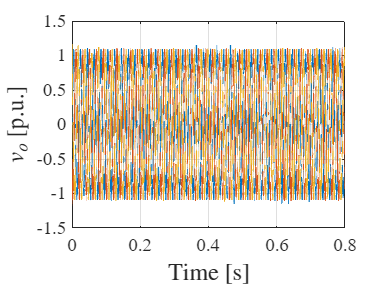

figure;

t = Vo.time;

grid on
hold on
plot(t, Vo.signals.values, LineWidth=1)
plot(t(120000:end), .7*ones(1, length(t(120000:end))), LineStyle="--", Color="k", LineWidth=2)
plot(t(120000:end), -.7*ones(1, length(t(120000:end))), LineStyle="--", Color="k", LineWidth=2)
% xline(1, LineStyle= "--", LineWidth=2, Color="k")
% xlim([0 0.8])
% ylim([-1.3 1.3])
xlabel("Time [s]")
ylabel("$v_o$ [p.u.]")
% xticks([.9 1 1.4])

ax = gca;
set(ax, axopts);
set(ax.XLabel, XLabelopts);
set(ax.YLabel, YLabelopts);
% annotation("textarrow", [.75, .8], [.8, .75], String="$\approx 0.65$ p.u.", Interpreter="latex", FontSize=14)
exportgraphics(gcf, "./fig/Vo_gfl10.eps");

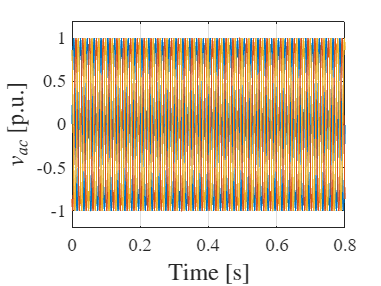

figure;

grid on 
hold on

plot(t, Vac.signals.values/Vnom_AC*sqrt(3/2), LineWidth=.5)
% plot(t(110000:end), .3*ones(1, length(t(110000:end))), LineStyle="--", Color="k", LineWidth=2)
% plot(t(110000:end), -.3*ones(1, length(t(110000:end))), LineStyle="--", Color="k", LineWidth=2)
% xline(1, LineStyle= "--", LineWidth=2, Color="k")
% xlim([.9 1.4])
ylim([-1.2 1.2])
xlabel("Time [s]")
ylabel("$v_{ac}$ [p.u.]")
% xticks([.9 1 1.4])

ax = gca;
set(ax, axopts);
set(ax.XLabel, XLabelopts);
set(ax.YLabel, YLabelopts);
% annotation("textarrow", [.75, .8], [.7, .64], String="$= 0.3$ p.u.", Interpreter="latex", FontSize=14)
exportgraphics(gcf, "./fig/Vac_gfl10.eps");

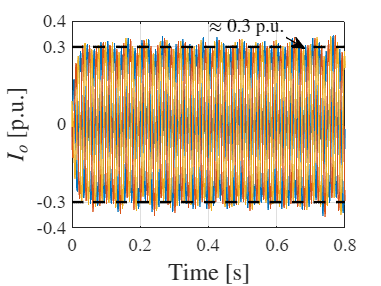

figure;

grid on 
hold on

plot(t, Io.signals.values, LineWidth=.5)
plot(t, .3*ones(1, length(t)), LineStyle="--", Color="k", LineWidth=2)
plot(t, -.3*ones(1, length(t)), LineStyle="--", Color="k", LineWidth=2)
% xline(1, LineStyle= "--", LineWidth=2, Color="k")
% xlim([.9 1.4])
% ylim([-2 2.3])
xlabel("Time [s]")
ylabel("$I_o$ [p.u.]")
% xticks([.9 1 1.4])
yticks([-.4 -.3 0 .3 .4])

ax = gca;
set(ax, axopts);
set(ax.XLabel, XLabelopts);
set(ax.YLabel, YLabelopts);
annotation("textarrow", [.75, .8], [.87, .83], String="$\approx 0.3$ p.u.", Interpreter="latex", FontSize=14)
exportgraphics(gcf, "./fig/Io_gfl10.eps");

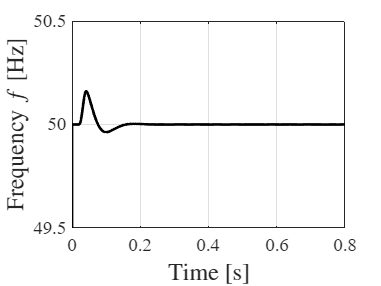

figure;

grid on 
hold on

plot(t, freq.signals.values, LineWidth=2, Color="k")
% xline(1, LineStyle= "--", LineWidth=2, Color="k")
% xlim([0 3])
ylim([49.5 50.5])
xlabel("Time [s]")
ylabel("Frequency $f$ [Hz]")
% xticks([0 1 3])

ax = gca;
set(ax, axopts);
set(ax.XLabel, XLabelopts);
set(ax.YLabel, YLabelopts);
% annotation("textarrow", [.75, .8], [.72, .65], String="$\approx 0.7$ p.u.", Interpreter="latex", FontSize=14)
exportgraphics(gcf, "./fig/f_gfl10.eps");